clear
clc
syms AA BA CA AB BB CB  PT PA PB t XA YA tp xk tee yp xp xee
% Diagrama de equilibrio líquido - vapor
AA=6.853

AA = 6.8530

BA=1064.84

BA = 1.0648e+03

CA=232.012

CA = 232.0120

AB=6.876

AB = 6.8760

BB=1171.17

BB = 1.1712e+03

CB=224.408

CB = 224.4080

PT=760

PT = 760

A12=1.6383

A12 = 1.6383

A21=0.9419

A21 = 0.9419

% Datos de alimentación y destilado
XWi=0.2

XWi = 0.2000

XDi=0.8

XDi = 0.8000

F=1000

F = 1000

Rop=5/3

Rop = 1.6667

P=1

P = 1

q=0.5

q = 0.5000

XFi=0.4

XFi = 0.4000

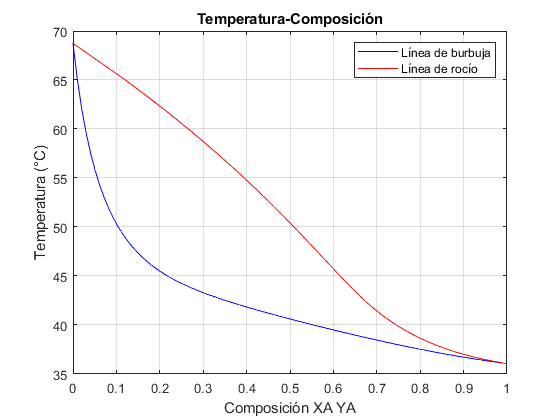


% Simbología
% R= Recirculado  F= Alimentación(Kmol/h) XWi= Recuperado de i en el reciduo
% XDi= Recuperado de i en el destilado P=Presión (atm)  q=Fracción líquida

XA=linspace(0,1,100);
ga=exp(1).^(A12.*((1+(A12.*XA)./(A21*(1-XA))).^-2));
gb=exp(1).^(A21.*((1+(A21.*(1-XA))./(A12.*XA)).^-2));

T=zeros(1,100);
for i=1:1:100
T(1,i)=vpasolve((ga(1,i)*10^(AA-BA/(CA+t))*XA(1,i))/PT+(gb(1,i)*10^(AB-BB/(CB+t))*(1-XA(1,i)))/PT==1,t);
end
YA=ga.*((10.^(AA-BA./(CA+T)))./PT).*XA;

%displayFormula('(q/(q-1))*(PT-gb*10^(AB-BB/(CB+tp)))/(ga*10^(AA-BA/(CA+tp))-gb*10^(AB-BB/(CB+tp)))+XFi/(1-q)==(ga*(10^(AA-BA/(CA+tp)))/PT)*(PT-gb*10^(AB-BB/(CB+tp)))/(ga*10^(AA-BA/(CA+tp))-gb*10^(AB-BB/(CB+tp)))')
eq1=yp==exp(1)^(A12*((1+(A12*xp)/(A21*(1-xp)))^-2))*((10^(AA-BA/(CA+tp)))/PT)*xp;
eq2=yp+(exp(1)^(A21*((1+(A21*(1-xp))/(A12*xp))^-2))*10^(AB-BB/(CB+tp))*(1-xp))/PT==1;
eq3=yp==(q/(q-1))*xp-XFi/(q-1);

[tp,xp,yp]=vpasolve(eq1,eq2,eq3);

plot(XA,T,'b')
hold on
plot(YA,T,'r')
xlabel('Composición XA YA')
ylabel('Temperatura (°C)')
legend('Línea de burbuja','Línea de rocío')
grid on
title('Temperatura-Composición')
hold off

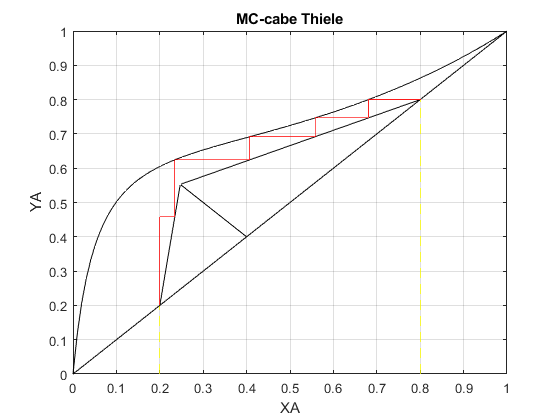


% MC cabe thiele

%Línea de composición de destilado
X_D=[XDi,XDi];
Y_D=[0,XDi];

%Línea de composición del residuo
X_W=[XWi,XWi];
Y_W=[0,XWi];

% Linea LOZE


bLOZEmin=XDi*(1-((yp-XDi)/(xp-XDi)));
Rmin=XDi/bLOZEmin-1;
Rop=Rop*Rmin;
bLOZE=XDi/(Rop+1);

xk=vpasolve((q/(q-1))*xk+XFi/(1-q)==(Rop/(Rop+1))*xk+XDi/(Rop+1),xk);
yk=(q/(q-1))*xk+XFi/(1-q);
X_k=[XDi,xk];
Y_k=[XDi,yk];

%línea q
X_q=[XFi,xk];
Y_q=[XFi,yk];

% Línea LOZA
%yLOZA=((yk-XWi)/(xk-XWi))*x+bLOZA
bLOZA=XWi*(1-(yk-XWi)/(xk-XWi));
S=-XWi/bLOZA;
X_LOZA=[XWi,xk];
Y_LOZA=[XWi,yk];

%Líneas de etapas de equilibrio
xe(1,1)=XDi;
ye(1,1)=XDi;

ER=0; %contador de etapas de rectificación 
EA=0; %contador de etapas de agotamiento

te(1,1)=vpasolve(xe(1,1)==(PT-exp(1)^(A21*(1+(A21*(1-xe(1,1)))/(A12*xe(1,1)))^-2)*10^(AB-BB/(CB+tee)))/((exp(1)^(A12*(1+((A12*xe(1,1))/(A21*(1-xe(1,1)))))^-2)*10^(AA-BA/(CA+tee))-exp(1)^(A21*((1+(A21*(1-xe(1,1))/(A12*xe(1,1))))^-2))*10^(AB-BB/(CB+tee)))),tee);
j=2;

while xe(1,j-1)>XWi
   
    [te(1,j),xe(1,j)]=vpasolve(ye(1,j-1)==(exp(1)^(A12*((1+(A12*xee)/(A21*(1-xee)))^-2))*((10^(AA-BA/(CA+tee)))/PT)*xee),((exp(1)^(A12*((1+(A12*xee)/(A21*(1-xee)))^-2)))*10^(AA-BA/(CA+tee))*xee)/PT+(((exp(1)^(A21*((1+(A21*(1-xee))/(A12*xee))^-2)))*10^(AB-BB/(CB+tee))*(1-xee)))/PT==1);
    ye(1,j)=(exp(1)^(A12*((1+(A12*xe(1,j))/(A21*(1-xe(1,j))))^-2))*(10^(AA-BA/(CA+te(1,j))))/PT)*xe(1,j);
    xe(1,j+1)=xe(1,j);
    
   if xe(1,j)>=xk
      ye(1,j+1)=Rop/(Rop+1)*xe(1,j+1)+bLOZE;
      ER=ER+1;
   elseif (xe(1,j)<xk) && (xe(1,j)>=XWi)
       ye(1,j+1)=((yk-XWi)/(xk-XWi))*xe(1,j+1)+bLOZA;
       EA=EA+1;
   else
       xe(1,j)=XWi;
       ye(1,j+1)=XWi;
       xe(1,j+1)=XWi;
   end
   j=j+2;
end



plot(XA,YA,'k')
xlabel('XA')
ylabel('YA')
grid on
title('MC-cabe Thiele')
hold on

plot([0 1],[0 1],'k')
plot(X_D,Y_D,'--y')
plot(X_W,Y_W,'--y')
plot(X_q,Y_q,'k')
plot(X_k,Y_k,'k')
plot(X_LOZA,Y_LOZA,'k')
plot(xe,ye,'r')
hold off